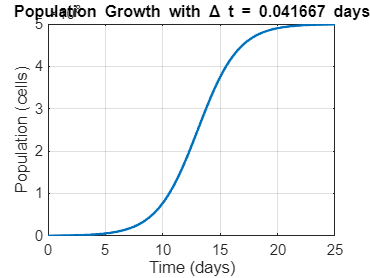

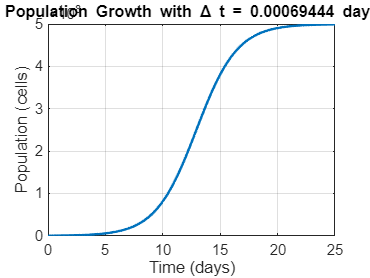

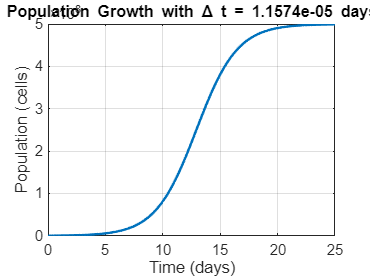

% Define parameters
K = 5e8; % Carrying capacity (cells)
r = 0.56; % Growth rate (cells per day)
P0 = 3000 * 120; % Initial population (cells)
time_intervals = [1/24, 1/1440, 1/86400]; % Time intervals in days (hour, minute, second)

% Define time span
T = 25; % Total time in days

% Preallocate arrays to store population at 3 days for each time interval
P_at_3_days = zeros(length(time_intervals), 1);

% Loop through each time interval
for i = 1:length(time_intervals)
    dt = time_intervals(i);
    t = 0:dt:T; % Time vector
    P = zeros(size(t)); % Population vector
    P(1) = P0; % Initial population
    
    % Euler method
    for j = 1:length(t)-1
        dPdt = r * P(j) * (1 - P(j) / K); % Differential equation
        P(j+1) = P(j) + dPdt * dt; % Euler update
    end
    
    % Save the population at 3 days
    [~, idx] = min(abs(t - 3)); % Find the index closest to 3 days
    P_at_3_days(i) = P(idx);
    
    % Plot the results for the current time interval
    figure;
    plot(t, P, 'LineWidth', 1.5);
    xlabel('Time (days)');
    ylabel('Population (cells)');
    title(['Population Growth with \Delta t = ', num2str(dt), ' days']);
    grid on;
end


% Display the population values at 3 days for each time interval
P_at_3_days

P_at_3_days = 1.0e+06 *

    1.8890
    1.9249
    1.9255
